10.1.1 Consider the hypothesis test H0: μ1 = μ2 against H1: μ1

≠ μ2 with known variances σ1 = 10 and σ2 = 5. Suppose that

sample sizes n1 = 10 and n2 = 15 and that x1 = 4.7 and x2 = 7.8.

Use α = 0.05.


$$P\left(\frac{\left(\mathrm{X1}-\mathrm{X2}\right)-\left(\mu {\;}_1 -\mu {\;}_2 \right)}{\sqrt{\;\sigma {\;}_2^1 /n_1 +\sigma {\;}_2^2 /n_2 }}<Z_{\frac{\alpha }{\;2}} \right)=1-\alpha \;$$


alpha = 0.05; 
x1 = 4.7; 
x2 = 7.8;
n1 = 10; 
n2 = 15; 
sigma1 = 10; 
sigma2 = 5;

a. Test the hypothesis and find the P-value.

z_a = norminv(1-0.05/2)

z_a = 1.9600

syms x 
z_0 = (x1-x2)/sqrt((((sigma1^2)/n1)+((sigma2^2)/n2)))

z_0 = -0.9076

g = normcdf(abs(z_0))

g = 0.8180

-0.9 ligger mellem -1.96 og 1.96, så vi afviser ikke null hypothesis. 

Pvalue =(1-g)*2 

Pvalue = 0.3641

b. Explain how the test could be conducted with a confidence

interval.

dif = x1-x2; 
up = dif + z_a*sqrt(sigma1^2/n1+sigma2^2/n2)

up = 3.5946

low = dif - z_a*sqrt(sigma1^2/n1+sigma2^2/n2) 

low = -9.7946

*With 95% confidence, the true difference in the means is between −9.79 and 3.59. Because zero is contained in this interval, we conclude there is no significant difference between the means. We fail to reject the null hypothesis.*

*Consider the hypothesis test H0 : μ1 = μ2 against H1: μ1 ≠ μ2. Suppose that sample sizes are n1 = 15 and n2 = 15, that x1 = 4.7 and x2 = 7.8, and that *$s{\;}_1^2$* = 4 and *$s{\;}_2^2$* = 6.25. Assume that *$\sigma {\;}_1^2$*= *$\sigma {\;}_2^2$* and that the data are drawn from normal distributions.*

*Use α = 0.05.*

alpha = 0.05; 
x1 = 4.7; 
x2 = 7.8;
n2 = 15; 
n = 15;
s1 = 4

s1 = 4

s2 = 6.25

s2 = 6.2500

%sigma1 = sigma2; 

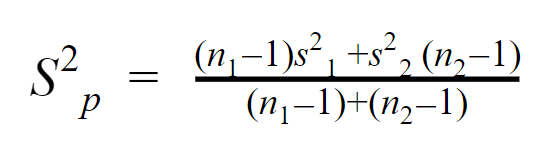

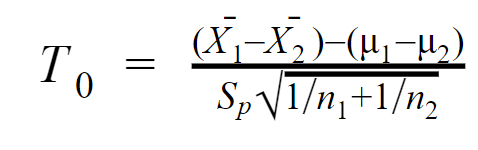

*a. Test the hypothesis and find the P-value.*

Sp = sqrt(((n-1)*s1+s2*(n2-1))/((n-1)+(n2-1)))

Sp = 2.2638


t0 = (x1-x2)/(Sp*sqrt((1/n)+(1/n2)))   

t0 = -3.7501

 Because −3.75 <-2.048, reject the null hypothesis at α = 0.05

pvalue = tcdf(t0,n1+n2-1.96)

pvalue = 5.2087e-04

*b. Explain how the test could be conducted with a confidence*

*interval.*

t = tinv(1-0.05/2,n-1+n2-1)

t = 2.0484


dif = x1-x2; 
up = dif + t*sqrt(s1/n+s2/n2)

up = -1.4067

low = dif - t*sqrt(s1/n+s2/n2)

low = -4.7933

Because zero is not contained in this interval, we reject the null hypothesis that the means are equal.

10.2.6 .WP VS Two suppliers manufacture a plastic gear used

in a laser printer. The impact strength of these gears measured

in foot-pounds is an important characteristic. A random sample

of 10 gears from supplier 1 results in x1 = 290 and s1 = 12, and another random sample of 16 gears from the second supplier

results in x2 = 321 and s2 = 22.

x1 = 290; 
s1 = 12; 
n1 = 10

n1 = 10

n2 = 16; 
x2 = 321; 
s2 = 22; 
alpha = 0.05; 
z_a = norminv(1-alpha/2)

z_a = 1.9600

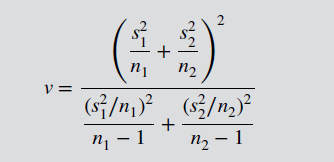

If v is not an integer, round down to the nearest integer.

a. Is there evidence to support the claim that supplier 2 provides gears with higher mean impact strength? Use α = 0.05, and assume that both populations are normally distributed but the variances are not equal. 

 Reject the null hypothesis if t0 < −tα,ν

t0 = (x1-x2)/sqrt(s1^2/n1+s2^2/n2)

t0 = -4.6393

up = (((s1^2/n1)+(s2^2/n2))^2)

up = 1.9936e+03

ll = ((s1^2/n1)^2/(n1-1))

ll = 23.0400

lr = ((s2^2/n2)^2/(n2-1))

lr = 61.0042

v1 = (up/(ll+lr))

v1 = 23.7211

v = 23

v = 23

talpha = tinv(1-0.05,v)

talpha = 1.7139

Reject the null hypothesis if t0 < −tα,ν, and since -4.63 < 1.71 we can actually reject it. 

What is the P-value for this test?

pvalue = tcdf(t0,n1+n2)

pvalue = 4.3552e-05

b. Do the data support the claim that the mean impact

strength of gears from supplier 2 is at least 25 foot-pounds

higher than that of supplier 1? Make the same assumptions

as in part (a).

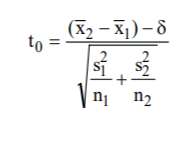

t0 = ((x2-x1)-25)/sqrt(s1^2/n1+s2^2/n2)

t0 = 0.8979

Because 0.898 < 1.714, fail to reject the null hypothesis. There is insufficient evidence to conclude that t the mean impact strength from supplier 2 is at least 25 ft-lb higher that supplier 1 using α = 0.05.

c. Construct a confidence interval estimate for the

difference in mean impact strength, and explain how this

interval could be used to answer the question posed regarding

supplier-to-supplier differences.

t = tinv(1-0.05/2,v);
upper = x2-x1+t*sqrt(s1^2/n1+s2^2/n2)

upper = 44.8229

lower = x2-x1-t*sqrt(s1^2/n1+s2^2/n2)

lower = 17.1771

Because zero is not contained in the confidence interval, we conclude that supplier 2 provides gears with a higher mean impact strength than supplier 1 with 95% confidence. 

10.2.11 .WP . SS The overall distance traveled by a golf ball is

tested by hitting the ball with Iron Byron, a mechanical golfer

with a swing that is said to emulate the distance hit by the legendary

champion Byron Nelson. Ten randomly selected balls of

two different brands are tested and the overall distance measured.

The data follow:

clear
Brand1 = [275 286 287 271 283 271 279 275 263 267]

Brand1 =    275   286   287   271   283   271   279   275   263   267


Brand2 = [258 244 260 265 273 281 271 270 263 268]

Brand2 =    258   244   260   265   273   281   271   270   263   268


size = 10;


a. Is there evidence that overall distance is approximately

normally distributed? Is an assumption of equal variances

justified?

it is normally distributed: 

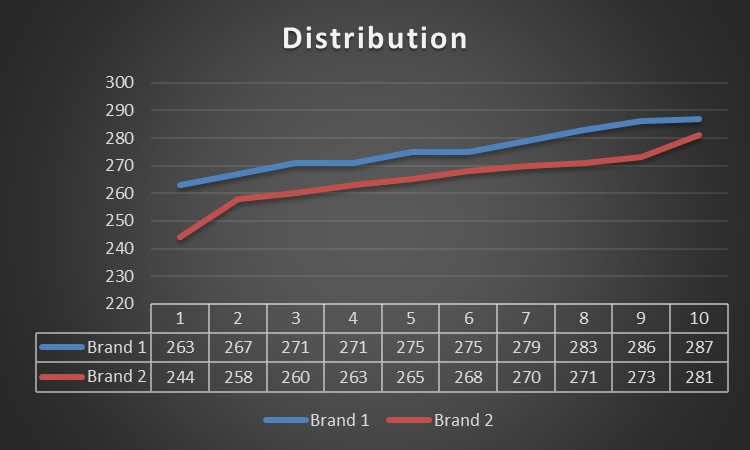

b. Test the hypothesis that both brands of ball have equal

mean overall distance. Use α = 0.05. What is the P-value?

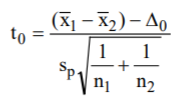for at anvende formlen skal vi finde mean og sp

%FIND MEAN 1
 A = 0;
for n = 1:size
 A = A+(1/size)*Brand1(1,n);
end
meanA = A

meanA = 275.7000

% variance^2 = S^2 - derfor regner vi lige variance ud. 
varA = 0;
for n = 1:size
 varA = varA+(1/(size-1))*((Brand1(1,n)-meanA)^2);
end
VarianceA = varA

VarianceA = 64.4556

S1 = sqrt(VarianceA)

S1 = 8.0284


%FIND MEAN 2
 B = 0;
for n = 1:size
 B = B+(1/size)*Brand2(1,n);
end
meanB = B

meanB = 265.3000


% variance^2 = S^2 - derfor regner vi lige variance ud. 
var = 0;
for n = 1:size
 var = var+(1/(size-1))*((Brand2(1,n)-meanB)^2);
end
Variance = var

Variance = 100.9000

S2 = sqrt(Variance)

S2 = 10.0449

Nu har vi både s1 og s2, sammen mean for begge datasæt. Så vi finder sp 

Sp = sqrt(((n-1)*S1^2+S2^2*(n-1))/((n-1)+(n-1)))

Sp = 9.0927

således kan vi finde t0

t0 = (meanA-meanB)/(Sp*sqrt(1/n+1/n))

t0 = 2.5575

Vi skal således sammenligne resultatet med $t_{\frac{\alpha }{2}} ,n+n-2$

t = tinv(1-0.05/2,n+n-2)

t = 2.1009

Conclusion: Because 2.558 > 2.101, reject the null hypothesis. The data support the claim that the means differ at α = 0.05

c. Construct a 95% two-sided CI on the mean difference in

overall distance for the two brands of golf balls.

upper = meanA-meanB+t*Sp*sqrt(1/n+1/n)

upper = 18.9432

lower = meanA-meanB-t*Sp*sqrt(1/n+1/n)

lower = 1.8568

d. What is the power of the statistical test in part (b) to detect a true difference in mean overall distance of 5 yards?

10.4.1 .WP The manager of a fleet of automobiles is testing two

brands of radial tires and assigns one tire of each brand at random

to the two rear wheels of eight cars and runs the cars until the tires

wear out. The data (in kilometers) follow. Find a 99% confidence

interval on the difference in mean life. Which brand would you

prefer based on this calculation?

clear
 Sheet = readtable('ch10.xlsx', 'Range', 'S3:S10');
 Brand1 = table2array(Sheet)

Brand1 =        36925
       45300
       36240
       32100
       37210
       48360
       38200
       33500


 
 Rowsize = size(Brand1);
 size = Rowsize(:,1)

size =      8


 
 Sheet1 = readtable('ch10.xlsx', 'Range', 'T3:T10');
 Brand2 = table2array(Sheet1)

Brand2 =        34318
       42280
       35500
       31950
       38015
       47800
       37810
       33215


vi skal anvende følgende formel: 

vi finder D hat ved følgende

% Dhat 
D = 0;
for n = 1:size
D = D+((Brand1(n,1)-Brand2(n,1))/size);
end
Dhat = D

Dhat =        868.38


således skal vi nu finde sd

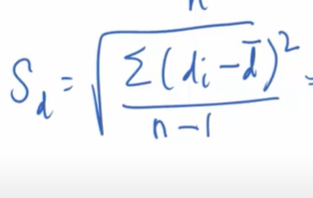

% Sd
format short g
sD = 0;
for n = 1:size
sD = sD + ((Brand1(n,1)-Brand2(n,1))-Dhat)^2;
end
SD = sqrt(sD/7)

SD =          1290


t = tinv(1-0.01/2,n-1)

t =        3.4995


up = Dhat-t*SD/sqrt(n)

up =       -727.72


low = Dhat+t*SD/sqrt(n)

low =        2464.5


Because this confidence interval contains zero, there is no significant difference between the two brands of tire at a 1% significance level.

10.4.3 .WP An article in the Journal of Aircraft [“Equivalent

Plate Analysis of Aircraft Wing Box Structures with General

Planform Geometry” (1986, Vol. 23, pp. 859–864)] described a

new equivalent plate analysis method formulation that is capable

of modeling aircraft structures such as cranked wing boxes

and that produces results similar to the more computationally

intensive finite element analysis method. Natural vibration frequencies

for the cranked wing box structure are calculated using

both methods, and results for the first seven natural frequencies

follow:

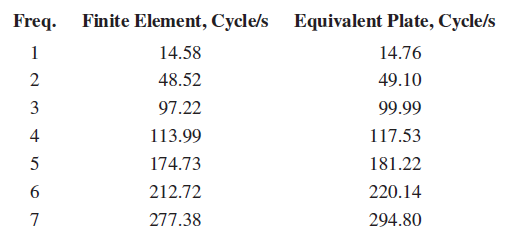

finite = [14.58 48.52 97.22 113.99 174.73 212.72 277.38]; 
Equivalent = [14.76 49.10 99.99 117.53 181.22 220.14 294.80];
size = 7; 

%Finite = 0;
%for n = 1:size
%Finite = Finite+(1/size)*finite(1,n);
%end
%MeanF = Finite

%Eq = 0;
%for n = 1:size
%Eq = Eq+(1/size)*Equivalent(1,n);
%end
%MeanE = Eq

a. Do the data suggest that the two methods provide the

same mean value for natural vibration frequency? Use α =

0.05. Find the P-value.

finite = [14.58 48.52 97.22 113.99 174.73 212.72 277.38]; 
Equivalent = [14.76 49.10 99.99 117.53 181.22 220.14 294.80];
size = 7; 

% Dhat 
D = 0;
for n = 1:size
D = D+((finite(1,n)-Equivalent(1,n))/size);
end
Dhat = D

Dhat =       -5.4857




% Sd
format short g
sD = 0;
for n = 1:size
sD = sD + ((finite(1,n)-Equivalent(1,n))-Dhat)^2;
end
SD = sqrt(sD/6)

SD =        5.9239


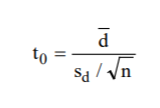

t0 = Dhat/(SD/sqrt(7))

t0 =       -2.4501


Conclusion: Because −2.45 < −2.447, reject the null hypothesis. The two methods have different mean values for natural vibration frequency at the 0.05 level of significance.

b. Find a 95% confidence interval on the mean difference

between the two methods.

t = tinv(1-0.05/2,6)

t =        2.4469


up = Dhat+t*SD/sqrt(n)

up =    -0.0070307


low = Dhat-t*SD/sqrt(n)

low =       -10.964


With 95% confidence, the mean difference between the natural vibration frequency from the equivalent plate method and the finite element method is between −10.969 and −0.011 cycles.